1.2 Basic system parameters

clear all % Remove all variables from memory
R = 10e6; % This defines the symbol rate in Hz or [sym/sec]
T = 1/R; % Corresponding symbol interval [s]
r = 4; % Oversampling factor (r samples per pulse)
Fs = r/T; % Sampling frequency
Ts = 1/Fs; % Sampling time interval

2 Basic Transmitter Processing

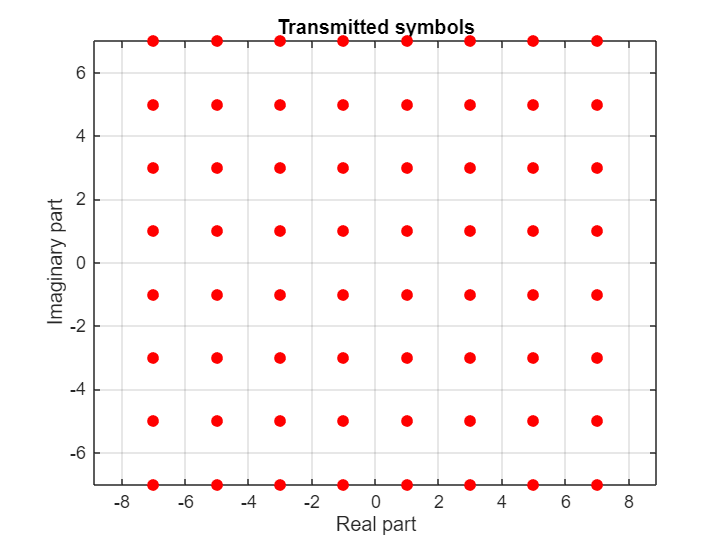

N_symbols = 10000; % Number of symbols to be transmitted
M = 64; % Modulation order
% Here qam_axis presents the symbol values per real/imaginary axis.
 % Below code is valid for values of M of the form 4, 16, 64, 256, 1024, ...
qam_axis =-sqrt(M)+1:2:sqrt(M)-1;
 
 %Generation of the complex constellation:
 %alphabet = bsxfun(@plus,qam_axis',1j*qam_axis);
 %Thisisequivalentto(alternative waytodothesamething)
 alphabet=repmat(qam_axis',1,sqrt(M))+repmat(1j*qam_axis,sqrt(M),1);
 alphabet=alphabet(:).';%Finallyrepresentalphabetsymbolsasarowvector
 %Thendrawarandomvectorofnumbersbetween1...M
 symbol_ind=randi(length(alphabet),1,N_symbols);

 symbols=alphabet(symbol_ind); %Randomsymbolsequencetobetransmitted
 %Plotthesymbols
 figure(1)
 plot(symbols,'ro','MarkerFaceColor','r')
 axis equal
 xlabel('Real part')
 ylabel('Imaginary part')
 title('Transmitted symbols')
 grid on

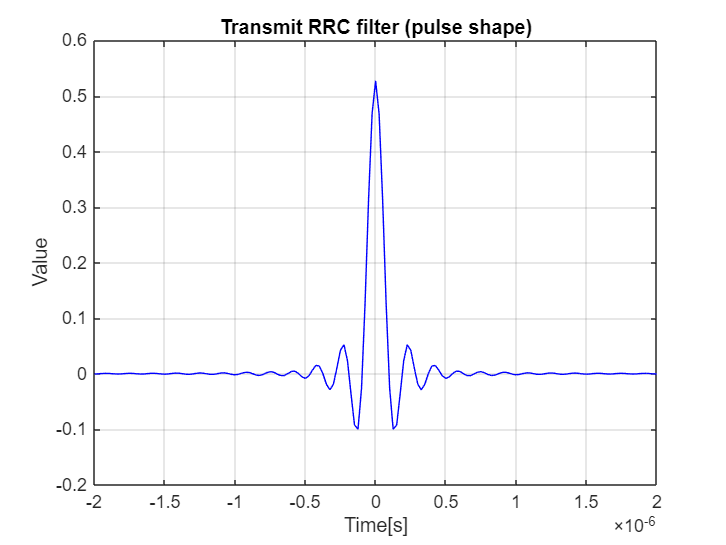

N_symbols_per_pulse=40; %Duration of TX pulse-shape filter in symbols
alpha=0.20; %Roll-off factor(excess bandwidth)
%Filter generation
gt=rcosdesign(alpha,N_symbols_per_pulse,r,'sqrt');
 %Plotthe pulseshapeofthetransmit/receivefilter
 figure(2)
 plot(-N_symbols_per_pulse*r/2*Ts:Ts:N_symbols_per_pulse*r/2*Ts,gt,'b')
 xlabel('Time[s]')
 ylabel('Value')
 title('Transmit RRC filter (pulse shape)')
 grid on

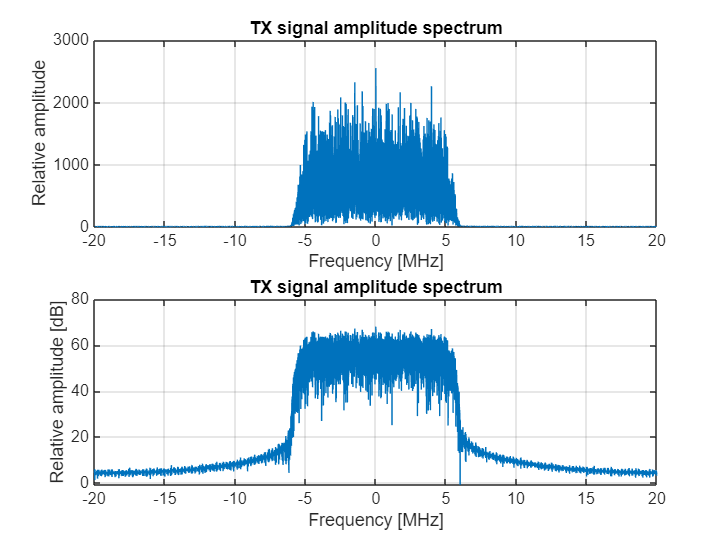


 symbols_upsampled=upsample(symbols,r);
 xt=filter(gt,1,symbols_upsampled); % Transmit pulse-shape filtering
 xt=xt(1+(length(gt)-1)/2:end); %Correct for the filter delay/transient
 NFFT=16384;%FFT size for spectrum analysis, here 2^14
 f=-Fs/2:1/(NFFT*Ts):Fs/2-1/(NFFT*Ts); % Frequency vector
 %Calculating and plotting the spectrum, in absolute scale and in dB
 figure(3)
 subplot(2,1,1);
 plot(f/1e6,fftshift(abs(fft(xt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('TX signal amplitude spectrum')
 subplot(2,1,2);
 plot(f/1e6,fftshift(20*log10(abs(fft(xt,NFFT)))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude [dB]')
 title('TX signal amplitude spectrum') 

Task 1:

The symbols are uniformly distributed. The sinc pulse shape shows the design of the transmit filter that helps to avoid intersymbol interference (ISI). The amplitude spectrum is centered at 0 Hz and the bandwidth is larger than the symbol rate because of the roll-off factor.

3 Noisy Multipath Channel Model

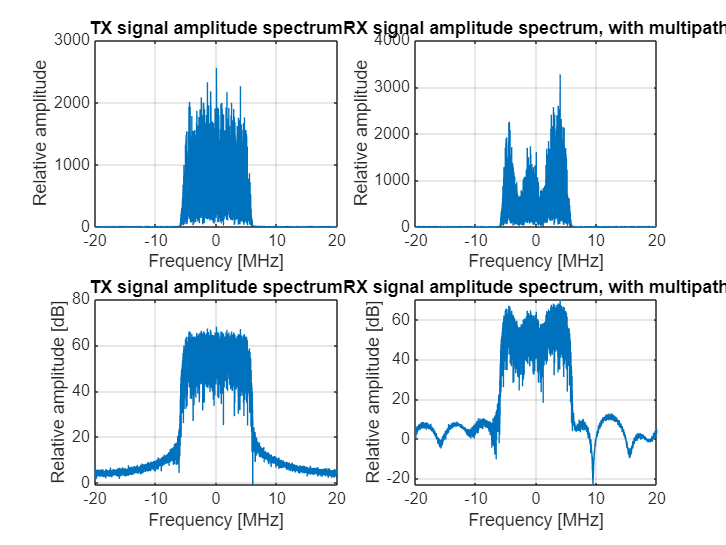

 b1=1;%means no multipath at all
 b2=[0.9-0.15j 0 -0.2-0.44j 0 0.1+0.36j];%some multipath components already
 b3=[0.8+0.2j 0 0 0 -0.3+0.68j 0 0 0 0 0.4-0.6j]/1.5;%more harsh multipaths
 %Theseexamplesare"fromthehat"butb2andb3anywayreflectscenarioswhere
 %therearetwoadditionalpathsontopofthemostdirectpath.(Butexact
 %multipathweightsarefromthehat)
 b=b3;
 yt=filter(b,1,xt);%Applying the multipath channel model to the signal
  figure(4)
 subplot(2,2,1);
 plot(f/1e6,fftshift(abs(fft(xt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('TX signal amplitude spectrum')
 subplot(2,2,3);
 plot(f/1e6,fftshift(20*log10(abs(fft(xt,NFFT)))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude [dB]')
 title('TX signal amplitude spectrum')
 subplot(2,2,2);
 plot(f/1e6,fftshift(abs(fft(yt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('RX signal amplitude spectrum, with multipath')
 subplot(2,2,4);
 plot(f/1e6,fftshift(20*log10(abs(fft(yt,NFFT)))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude [dB]')
 title('RX signal amplitude spectrum, with multipath')

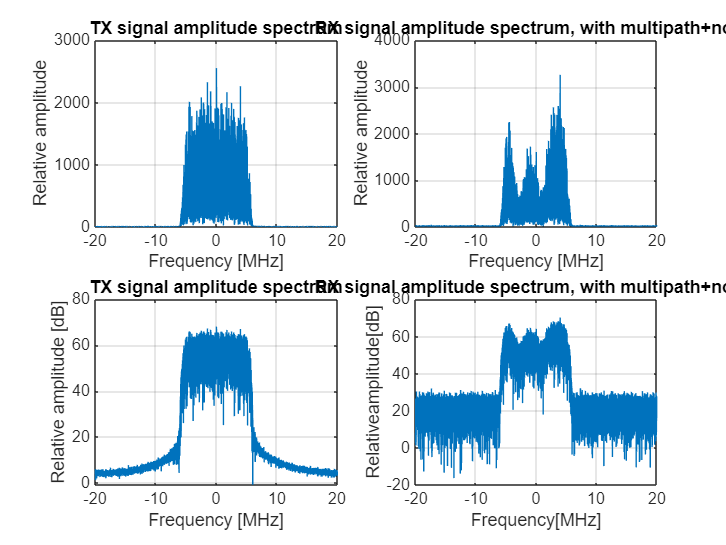


 SNRdB = 35; %Experimentedsignal-to-noiseratio[dB]
 %ComplexwhiteGaussiannoisesequence,firstofunitpower/variance
 n=(1/sqrt(2))*(randn(size(yt))+1j*randn(size(yt)));
 P_y=var(yt); %Signalpower
 P_n=var(n); %Noisepower
 %Defining noisescalingfactorbasedontheSNRlevel:
 noise_scaling_factor=sqrt(P_y/P_n./10.^(SNRdB./10)*(r/(1+alpha)));

 rt=yt+noise_scaling_factor*n;

 figure(5)
 subplot(2,2,1);
 plot(f/1e6,fftshift(abs(fft(xt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('TX signal amplitude spectrum')
 subplot(2,2,3);
 plot(f/1e6,fftshift(20*log10(abs(fft(xt,NFFT)))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude [dB]')
 title('TX signal amplitude spectrum')
 subplot(2,2,2);
 plot(f/1e6,fftshift(abs(fft(rt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('RX signal amplitude spectrum, with multipath+noise')
 subplot(2,2,4);
 plot(f/1e6,fftshift(20*log10(abs(fft(rt,NFFT)))));grid on;
 xlabel('Frequency[MHz]')
 ylabel('Relativeamplitude[dB]')
 title('RX signal amplitude spectrum, with multipath+noise')

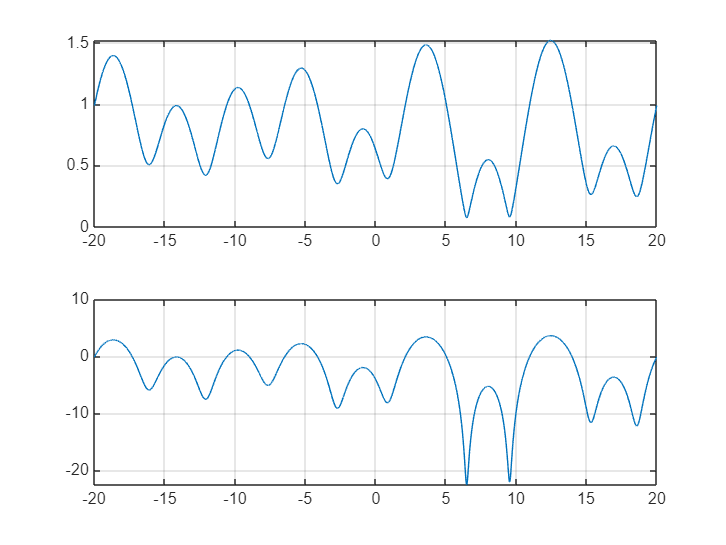

 figure(99)
 subplot(211)
 plot(f/1e6,fftshift(abs(fft(b,NFFT))));grid on;
 subplot(212)
 plot(f/1e6,fftshift(20*log10(abs(fft(b,NFFT)))));grid on;

Task 2:

When varying the SNRdB value, it is observed that the lower the values, the less distinguishable the  peaks corresponding to the transmitted signal are. The fading notches inside the passband are a result of destructive interference caused by the delayed multipath components, and the multipath channel attenuates and amplifies different frequency components. When the multipath channel is b1, there is no multipath, as can be seen in the flat amplitude response. There is multipath when the channel is b2 and b3, but the  channel b3 is harsh, so we observe that the fading notchesare deeper and more frequent. 

4 Basic Receiver Processing

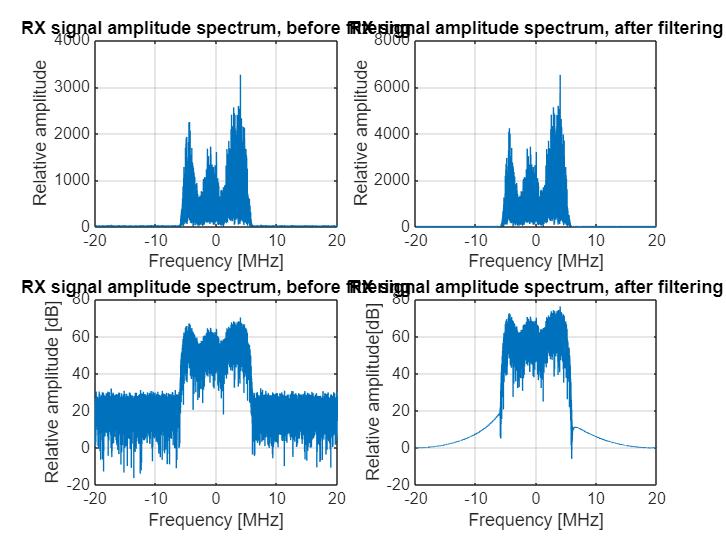

 %Creating thereceivefilterf(t)(it isherethesameasinthetransmitter)
 ft=gt;
 %ThenfilteringthereceivednoisysignalwiththechosenRXfilter
 qt=filter(ft,1,rt);%Receiverfiltering
 qt=qt(1+(length(ft)-1)/2:end);%Discardfilterdelay/transient
 figure(6)
 subplot(2,2,1);
 plot(f/1e6,fftshift(abs(fft(rt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('RX signal amplitude spectrum, before filtering')
 subplot(2,2,3);
 plot(f/1e6,fftshift(20*log10(abs(fft(rt,NFFT)))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude [dB]')
 title('RX signal amplitude spectrum, before filtering')
 subplot(2,2,2);
 plot(f/1e6,fftshift(abs(fft(qt,NFFT))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude')
 title('RX signal amplitude spectrum, after filtering')
 subplot(2,2,4);
 plot(f/1e6,fftshift(20*log10(abs(fft(qt,NFFT)))));grid on;
 xlabel('Frequency [MHz]')
 ylabel('Relative amplitude[dB]')
 title('RX signal amplitude spectrum, after filtering')

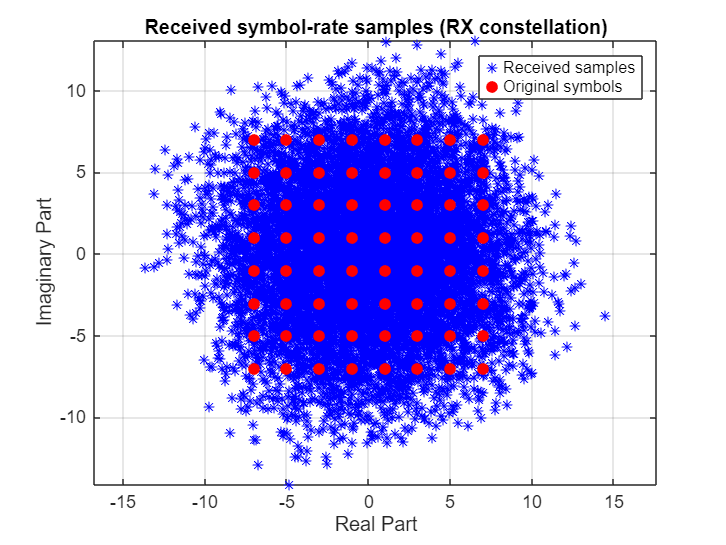

 %Sampling thefilteredRXsignalat symbolrate.Rememberthatweused
 %oversamplingintheTX,byafactorofr,sothisisnowjustpickingevery
 %r-thsample
 qk=qt(1:r:end);
 figure(7)
 plot(qk,'b*');hold on;grid on;
 plot(alphabet,'ro','MarkerFaceColor','r');hold off
 legend('Received samples','Original symbols')
 xlabel('Real Part')
 ylabel('Imaginary Part')
 title('Received symbol-rate samples (RX constellation)')
 axis equal

Task 3:

When there is no multipath effect and the SNR is set to relatively high, the received samples cluster tightly around the original symbols. When SNR is set to lower  20dB, the points will be more scattered compared to 35 dB but the signal is still reliably decodable. When the SNR is 10 dB, the noise significantly spreads the constellation samples, causing noticeable overlaping. The RX then is unable to decode the signal reliably. When the SNR is kept at 35dB, and the multipath effect is existent, the received samples are spread out and scattered from the original symbol. The sample pattern is rotated due to phase shifting, and the distortion is more serious when b3 is used. The samples are much less distinct. At a low SNR of 10 dB, when there is no multipath channel (b1), the distortion is due to the noise. When the multipath is b2 and b3, both noise and multipath effect distort the signal constellation. When the modulation order is set to M=4 and M = 64, it is observed that the RX signal constellation is able to decode the signal more easily at lower order because the original symbols are more widely spaced.

  Beta=100; %NoisebandwidthinHz
 %Generatephasenoisemodel,i.e.complexexponentialwithrandomphasejitter
 pt=phasenoise(numel(xt),Fs,Beta);

Unrecognized function or variable 'phasenoise'.

 %OmitAWGNnoiseandmultipathandaddphasenoise:
 %Theeffectontheusedwaveformismodeledbymultiplyingtheideal
 %waveformsampleswithgeneratedphasenoise
 rt=xt.*pt; %
 qt=filter(ft,1,rt);%Receiverfiltering
 qt=qt(1+(length(ft)-1)/2:end);%Discardfilterdelay/transient
 qk=qt(1:r:end);%Sampleatsymbolrate
 %Plotthe constellationfor1024symbols
 figure(8)
 plot(qk(1:1024),'b*');hold on;grid on;
 plot(alphabet,'ro','MarkerFaceColor','r');hold off
 legend('Receivedsamples','Original symbols')
 xlabel('Realpart')
 ylabel('Imaginarypart')
 title('Receivedsymbol-ratesamples(RXconstellation)')
 axis equal